# Estimate Optical Flow Using Horn-Schunck Method

Create a `VideoReader` object for the input video file, `visiontraffic.avi`. Specify the timestamp of the frame to read as 11. 

vidReader = VideoReader('visiontraffic.avi','CurrentTime',11);

Specify the optical flow estimation method as `opticalFlowHS`. The output is an object specifying the optical flow estimation method and its properties.

opticFlow = opticalFlowHS

opticFlow =   opticalFlowHS - 属性:

            Smoothness: 1
          MaxIteration: 10
    VelocityDifference: 0


Create a custom figure window to visualize the optical flow vectors.

h = figure;
movegui(h);
hViewPanel = uipanel(h,'Position',[0 0 1 1],'Title','Plot of Optical Flow Vectors');
hPlot = axes(hViewPanel);

Read image frames from the `VideoReader` object and convert to grayscale images. Estimate the optical flow from consecutive image frames. Display the current image frame and plot the optical flow vectors as quiver plot.

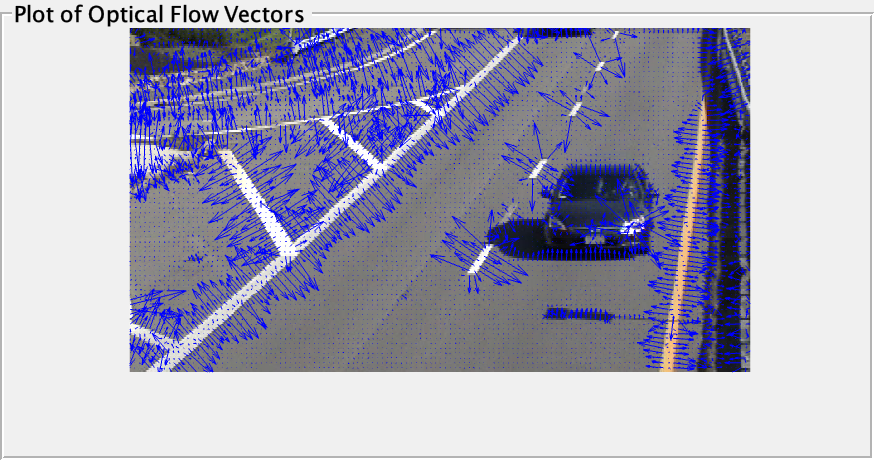

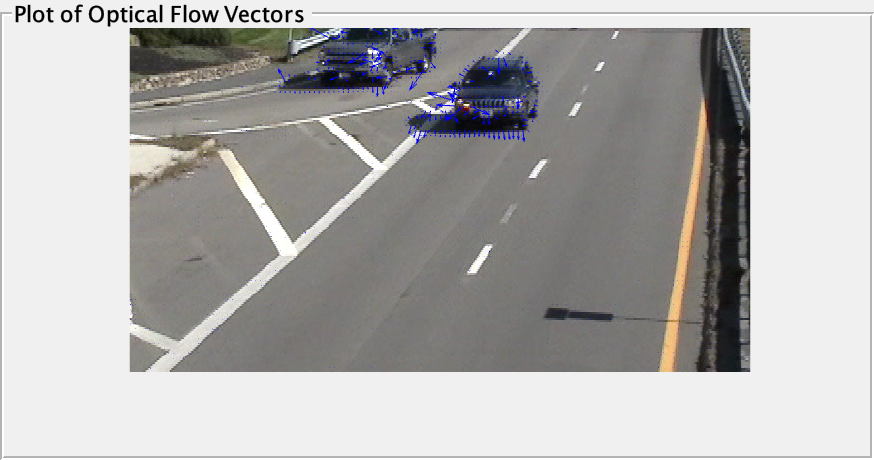

while hasFrame(vidReader)
    frameRGB = readFrame(vidReader);
    frameGray = rgb2gray(frameRGB);  
    flow = estimateFlow(opticFlow,frameGray);
    imshow(frameRGB)
    hold on
    plot(flow,'DecimationFactor',[5 5],'ScaleFactor',60,'Parent',hPlot);
    hold off
    pause(10^-3)
end

*Copyright 2015 The MathWorks, Inc.*